clear all
num1 = [0.5 5];
den1 = [0.5 1 0];
sys1 = tf(num1, den1);

num2 = [1];
den2 = [1/2500 0.6/50 1];
sys2 = tf(num2, den2);

sys = sys1*sys2

sys =
 
                 0.5 s + 5
  ---------------------------------------
  0.0002 s^4 + 0.0064 s^3 + 0.512 s^2 + s
 
연속시간 전달 함수입니다.
모델 속성


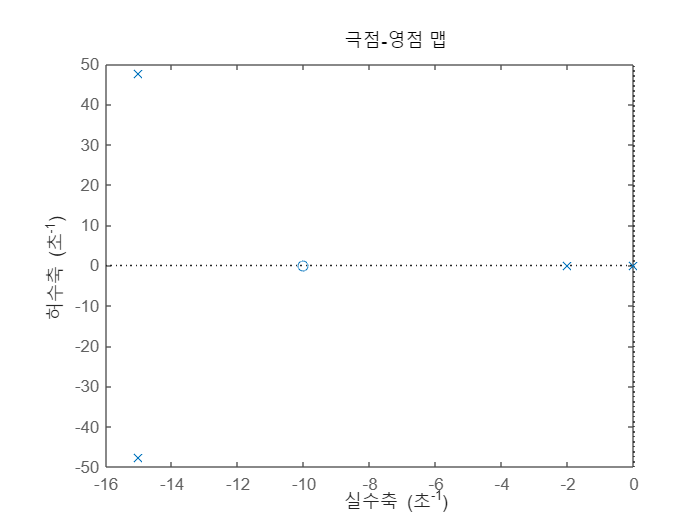

pzmap(sys);

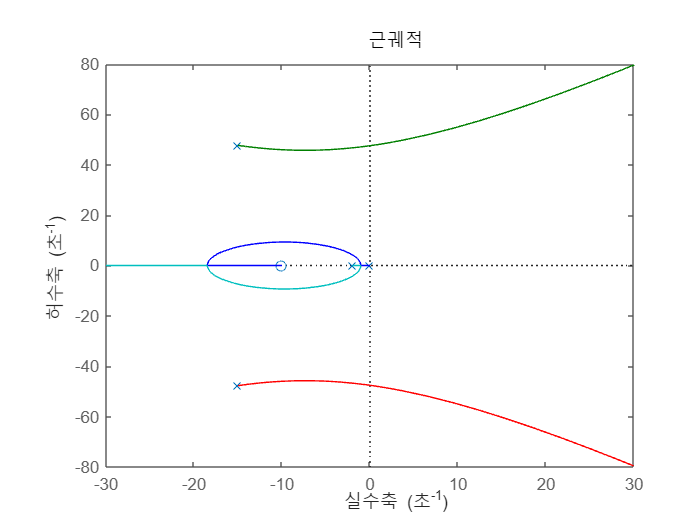

rlocus(sys);
axis([-30 30 -80 80]);

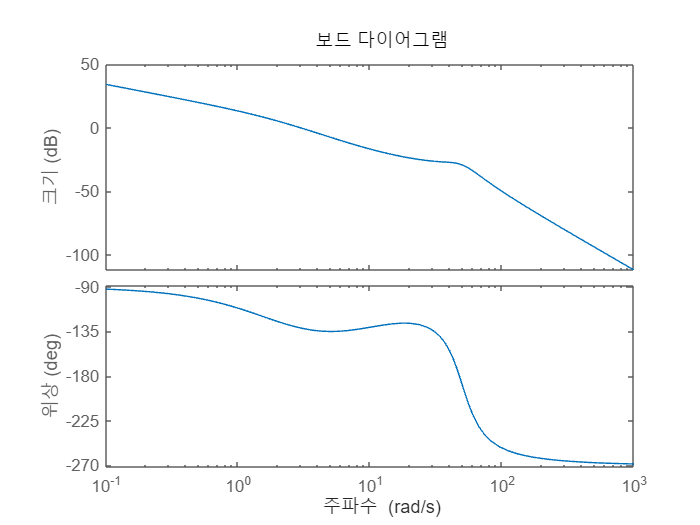

bode(sys)

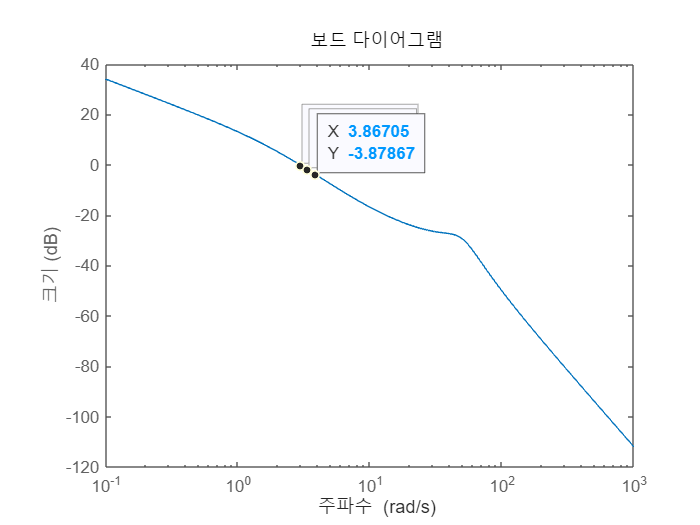

bodemag(sys)